# MATH2089 Week 10

In previous weeks, we tested for the difference of means between two popultions. This week we'll examine the difference of means between an arbitrary number of populations $P_{1},\dots,P_{K}$. Suppose that each population is distributed $N(\mu_{i},\sigma)$, for $i = 1,\dots,K$—so that each population is Normally distributed with the same variance, but possibly different means. We want to test if $\mu_{1}=\mu_{2}=\cdots=\mu_{K}$, so that all the population means are simultanesouly equal. 

From each population, we collect the samples


$$X_{11},\dots,X_{1n_1}$$



$$X_{21},\dots,X_{2n_2}$$



$$\vdots$$


$X_{K1},\dots,X_{Kn_K}$,

their associated sample means $\overline{X}_{1},\dots,\overline{X}_{K}$, and sample variances $S^{2}_{1},\dots,S^{2}_{K}$. Let $n = \sum^{k}_{i = 1} n_{i}$. Now, each $S^{2}_{i}$ is an unbiased estimate for $\sigma^{2}$. Hence


$$\text{MS}_{\text{Er}} = \frac{\text{SS}_{\text{Er}}}{n - k} = \frac{1}{n - k}\sum^{K}_{i=1}(n_{i} - 1)S^{2}_{i} = \frac{1}{n - k}\sum^{K}_{i = 1}\sum^{n_{i}}_{j = 1}\left(X_{ij} - \overline{X}_{i}\right)^{2}$$


is also an unbiased estimate for $\sigma^{2}$—in fact, $\text{MS}_{\text{Er}}$ is a better estimator since it has lower variance. We know that $S^{2}_{i}\sim\chi^{2}_{n_{i} - 1}}$, which implies that $\text{SS}_{\text{Er}}\sim\chi^{2}_{n - k}$. If our assumption of equality of means is true, then $\mu_{i} = \mu$ for $1\leq i\leq k$, which implies that $Y_{i} = \sqrt{n_{i}}\left(\overline{X}_{i} - \mu\right)\sim N(0,\sigma)$. Hence, if our assumption is true, then $Y_{1},\dots,Y_{k}$ is an indepdent and identically distributed Normal random sample. The mean zero property of the $Y_{i}$ implies that 


$$\frac{1}{k - 1}\sum^{k}_{i - 1} Y^{2}_{i} = \frac{1}{k - 1}\sum^{k}_{i = 1} \sqrt{n_i}\left(\overline{X}_{i} - \mu\right)^{2}$$


is an unbiased estimator for $\sigma^{2}$. Note that under the assumption of equality of means, $\overline{\overline{X}}$ is an unbiased estimate for $\mu$. Hence, we can replace $\mu$ above with $\overline{\overline{X}}$ and still have an unbiased estimator for $\sigma^{2}$, ie, 


$$\text{MS}_{\text{Tr}} = \frac{\text{SS}_{\text{Tr}}}{k-1} = \frac{1}{k - 1}\sum^{k}_{i = 1} \sqrt{n_i}\left(\overline{X}_{i} - \overline{\overline{X}}\right)^{2}$$


is an unbiased estimator for $\sigma^{2}$ under the assumption that $\mu_{1}=\cdots=\mu_{k} = \mu$. This implies that $\text{SS}_{\text{Tr}}\sim\chi^{2}_{k - 1}$. 

Note that we have a global assumption about distribution and equality of variance, which implied that $\text{MS}_{\text{Er}}$ is always an unbiased estimator for $\sigma^{2}$. However, $\text{MS}_{\text{Tr}}$ is only an unbiased estimator under the additionaly assumption of equality of variances. So if our assumption of equality of means is true, then $\text{MS}_{\text{Er}}\approx\text{MS}_{\text{Tr}}$. Usually $\text{MS}_{\text{Er}} < \text{MS}_{\text{Tr}}$. We can test the probability of equality using the $F$-test. In this case, our test statistic

$F = \frac{\text{MS}_{\text{Tr}} / (k - 1)}{\text{MS}_{\text{Er}} / (n - k)}\sim \mathbf{F}_{k - 1, n - k}$. 

Here, if $F$ is unusually large, then the estimate of the variance between groups is much larger than the estimate of variance from the individuals, and our initial assumption is probably incorrect. 

## Question 1

We want to examine if the time of day affects download speeds. We quantise the time of day into three categories: `early`, `evening`, and `late`. Our data is contained in the `downloads` text file. Note that each colum  here contains a header that describes the variable, `dtime` for the download time and `period` for the time of day when the file was downloaded. We can't use `readmatrix()` to import the file since `period` is a character vector and `readmatrix()` only supports numeric matrices. We'll use `readvars()` to output each column to a variable, and then convert `period` from a cell array to a categorical vector using the function `categorical()`.

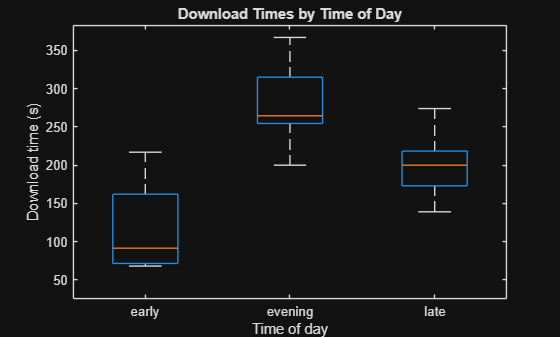

[dtime, period] = readvars("data/downloads.txt");

period = categorical(period);

boxplot(dtime, period);
xlabel("Time of day");
ylabel("Download time (s)");
title("Download Times by Time of Day");

Let's examine our model formally using `fitlm()`. We'll save our linear model to the object `downloadsMod`, which fits `dtime` as response and `period` as the regressor. 

downloadsMod = fitlm(period, dtime);

We make the following assumptions when fitting linear models with categorical regressors,

- The observations are independent within and between groups

- The random errors have mean zero

- The variance of reponses is equal between groups

- *(For hypothesis testing) *The random errors are Normally distributed

Criterion one can only be assessed through inspection of the study design. We can assess criteria two and four through average of the residuals and quantile plot. The average residuals for all observations across all groups is in the order of $10^{-15}$, which is very close to zero. The quantile plot of the residuals indicates that the residuals may not be Normally distributed. 

qqplot(downloadsMod.Residuals.Raw)

Finally, we compare the between group standard deviations. We apply the rule-of-thumb that *the group population variances are equal if the sample standard deviations are all within a factor of two of each other*. We respectively observe sample standard deviation of approximately `57`, `52`, and `41` for the `early`, `evening`, and `late` periods, all of which satisfy the rule-of-thumb. Hence, we shall assume that $\sigma_{\text{early}} = \sigma_{\text{evening}} = \sigma_{\text{late}}$. 

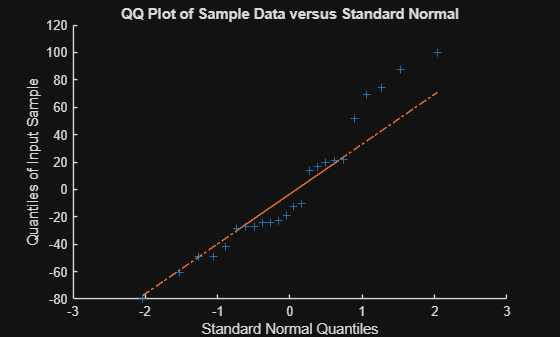

% help grpstats

[groupName, groupSize, groupMean, groupStD] = grpstats(dtime, period, {'gname', 'numel', 'mean', 'std'});
[string(groupName), groupStD]

We'll formalise our conjecture, where the mean download times are different for different periods in the day, through a hypothesis test. Let $\mu_{\text{early}}, \mu_{\text{evening}}$ and $\mu_{\text{late}}$ be the respective *true* mean download time for the periods `early`, `evening`, and `late`. We assume that the mean download times are all equal and test to see if *at least one mean download time is different*. Note that this only requires that only one of $\mu_{\text{early}}, \mu_{\text{evening}}$ and $\mu_{\text{late}}$ are different from the others, and not that they are all different. Our hypotheses are


$$H_{0}: \mu_{\text{morning}} = \mu_{\text{evening}} = \mu_{\text{night}}$$


$H_{1}:$ not all means are equal. 

We utilise the statistic 


$$F = \frac{\text{variance between treatments}}{\text{variance within treatments}} = \frac{MS_{\text{treatments}}}{MS_{\text{Error}}} = \frac{SS_{\text{treatments}} / (k - 1)}{SS_{\text{error}} / (n - 1)}$$


where $MS_{\text{treatments}}, MS_{\text{error}}, SS_{\text{treatments}}, SS_{\text{error}}, k$, and $n$ respectively denote the mean square errors within each treatment, the mean square error  between treatments, the sum of squared errors within each treatment, the sum of squared errors between treatments, the number of treatments, and the number of subjects. We know that $F\sim \mathbf{F}_{k - 1, n - k}$, where $\mathbf{F}_{k -1, n - k}$ is Fisher's $F$-distribution with degrees of freedom $k - 1$ and $n - k$. In this case, we have that $k$ `= 3` groups and $n$ `= 24` observations, so that $F\sim\mathbf{F}_{2, 21}$.

Our observed test statistic is $f$ `= 20.7202`, whose associated $p$-value is $p = \mathbb{P}(F > f)$ ` < 0.0001`. This implies that we have very strong evidence against the null hypothesis. This suggests that there is strong evidence that the average download times are not constant throughout the day, so that the time of day *does* affect download speeds.

[length(groupName), sum(groupSize)]
anova(downloadsMod)

Suppose that we want to compute a *pairwise ANOVA test*, i.e., compare the means between two of the categories. We have the hypotheses


$$H_{0}: \mu_{i} = \mu_{j}$$


$H_{1}: \mu_{i}\neq \mu_{j}$.

The associated test statistic is

$T = \frac{\overline{X}_{i} - \overline{X}_{j}}{\sqrt{MS_{\text{Error}}\left(\frac{1}{n_{i}} + \frac{1}{n_{j}}\right)}} \sim t_{n - k}$. 

We apply the regular hypothesis test methods, only now we also have the adjustment $\alpha / K$ for the critical level, where $K = {k\choose 2}$ is the number of pairwise comparisons that we can make. 

## Question 2

Let $\mu_{1}, \mu_{2}$, and $\mu_{3}$ respectively denote the true mean strength of the respective curing methods 1, 2,  and 3. Our null and alternative hypotheses are respectively


$$H_{0}: \mu_{1} = \mu_{2} = \mu_{3}$$



$$H_{a}: \text{at least one of the } \mu_{i} \text{ are different}$$


[method, batch, strength] = readvars("data/concrete.txt");

regressors = [method, batch];

concreteMod = fitlm(regressors, strength, 'CategoricalVars', [1, 2]);

anova(concreteMod)

The ANOVA table provides the variation in strength according to the `method` (in row 1) and `batch `(in row 2). We are interested in the variation due to the `method`. The data of interest with respect to the hypotheses test we wish to perform is contained in the first row. Our test statistic is

$F = \frac{\text{Mean Square Treatment}}{\text{Mean Square Error}}$,

with an observed value of

$f \approx \frac{11.6143}{1.3358} \approx 8.6946$.

concreteModMethodOnly = fitlm(method, strength, 'CategoricalVars', 1);
anova(concreteModMethodOnly)
